In the name of allah

# Linear Control Systems

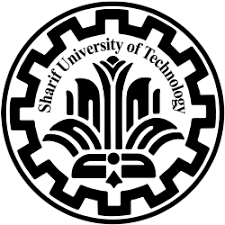

Hw 02

ali sadeghian 400101464

Fall 1402

# Theory Assignments

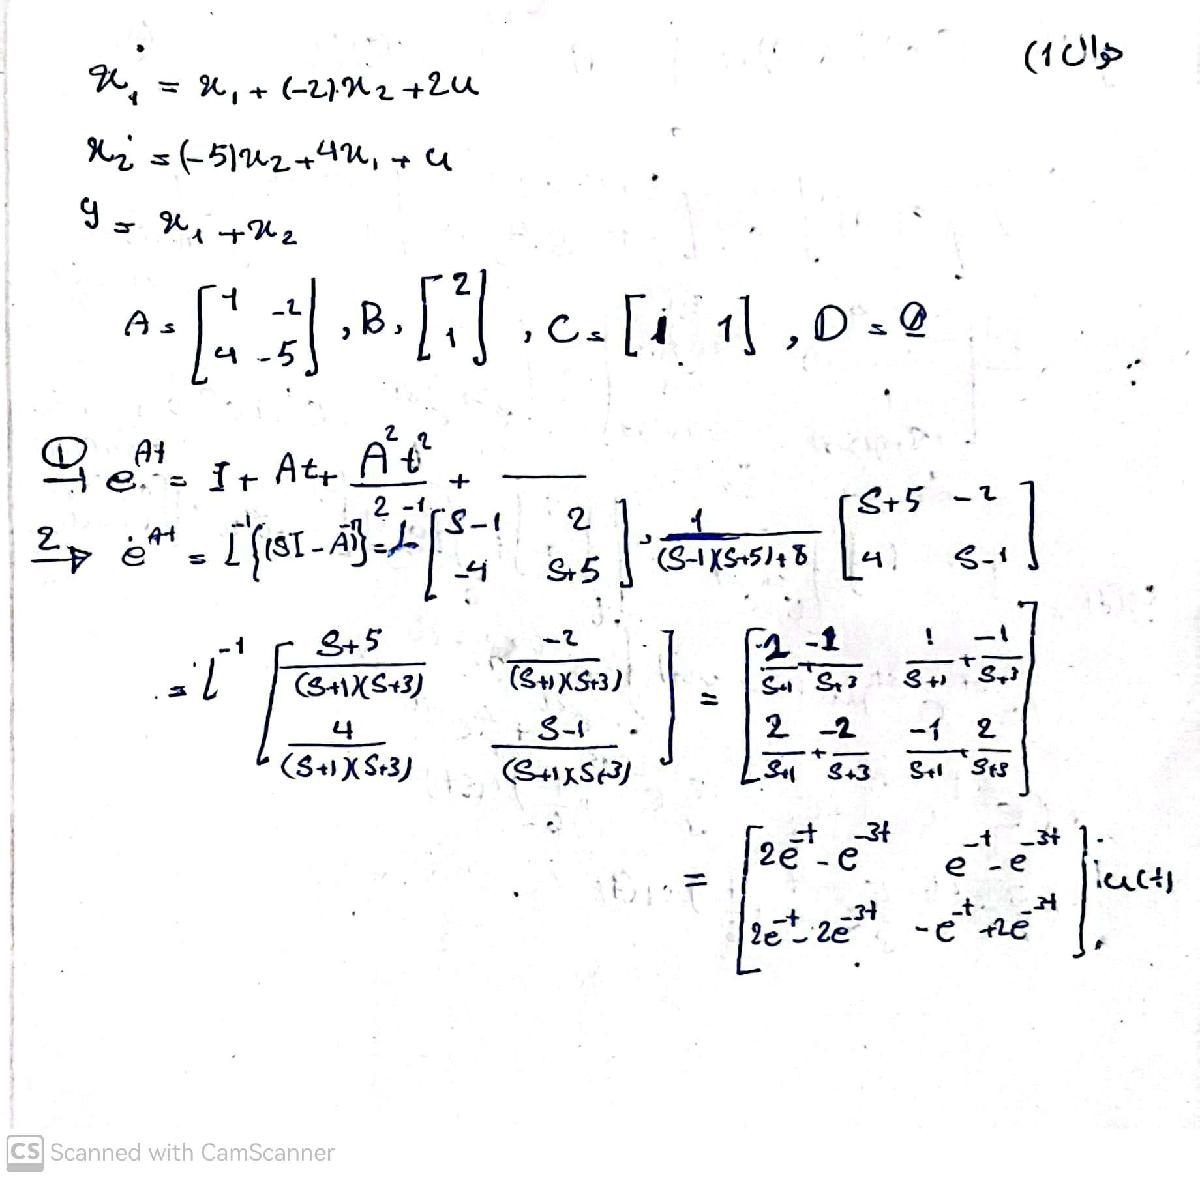

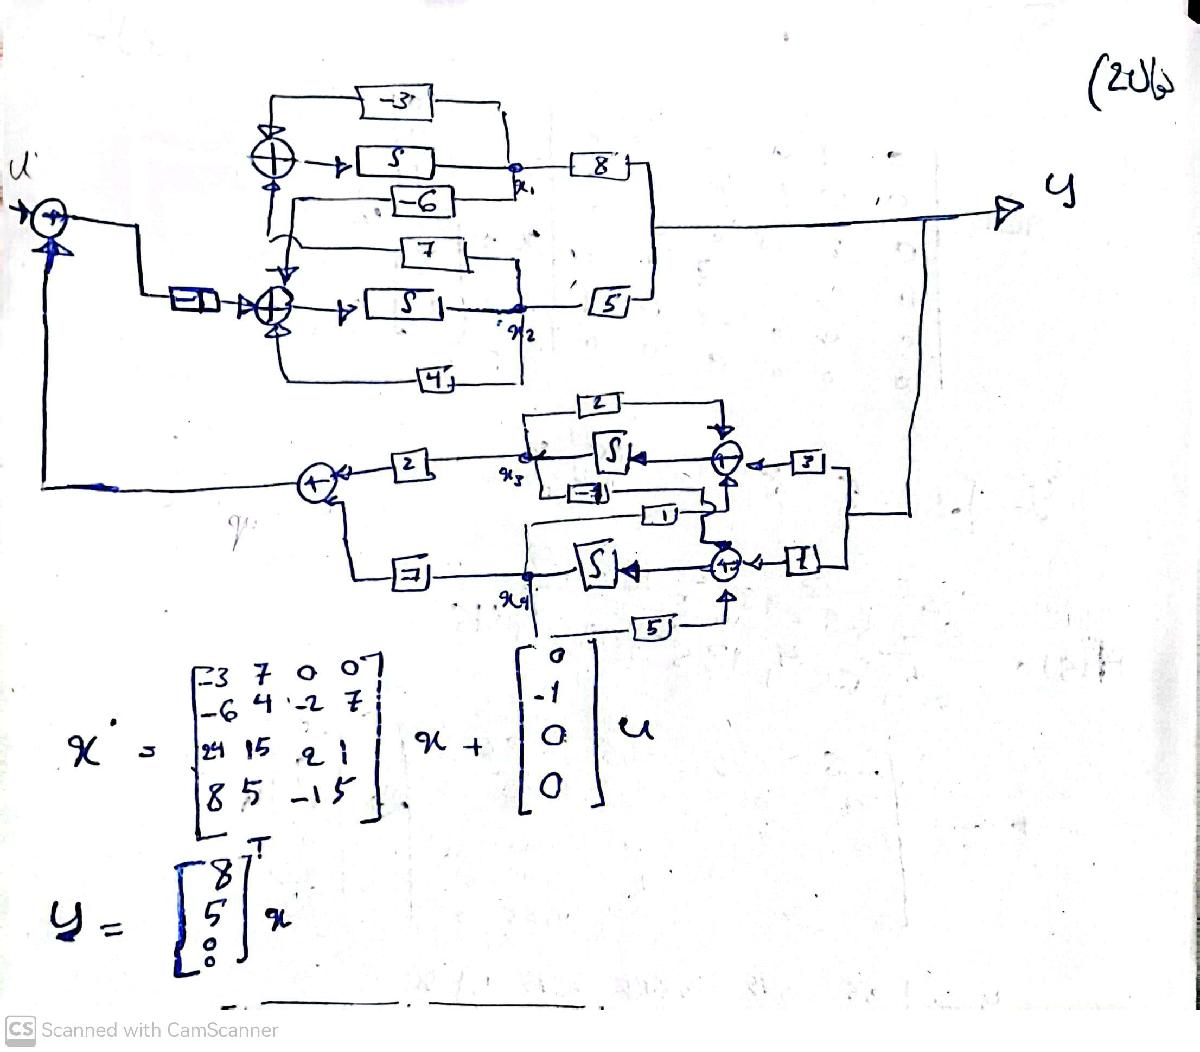

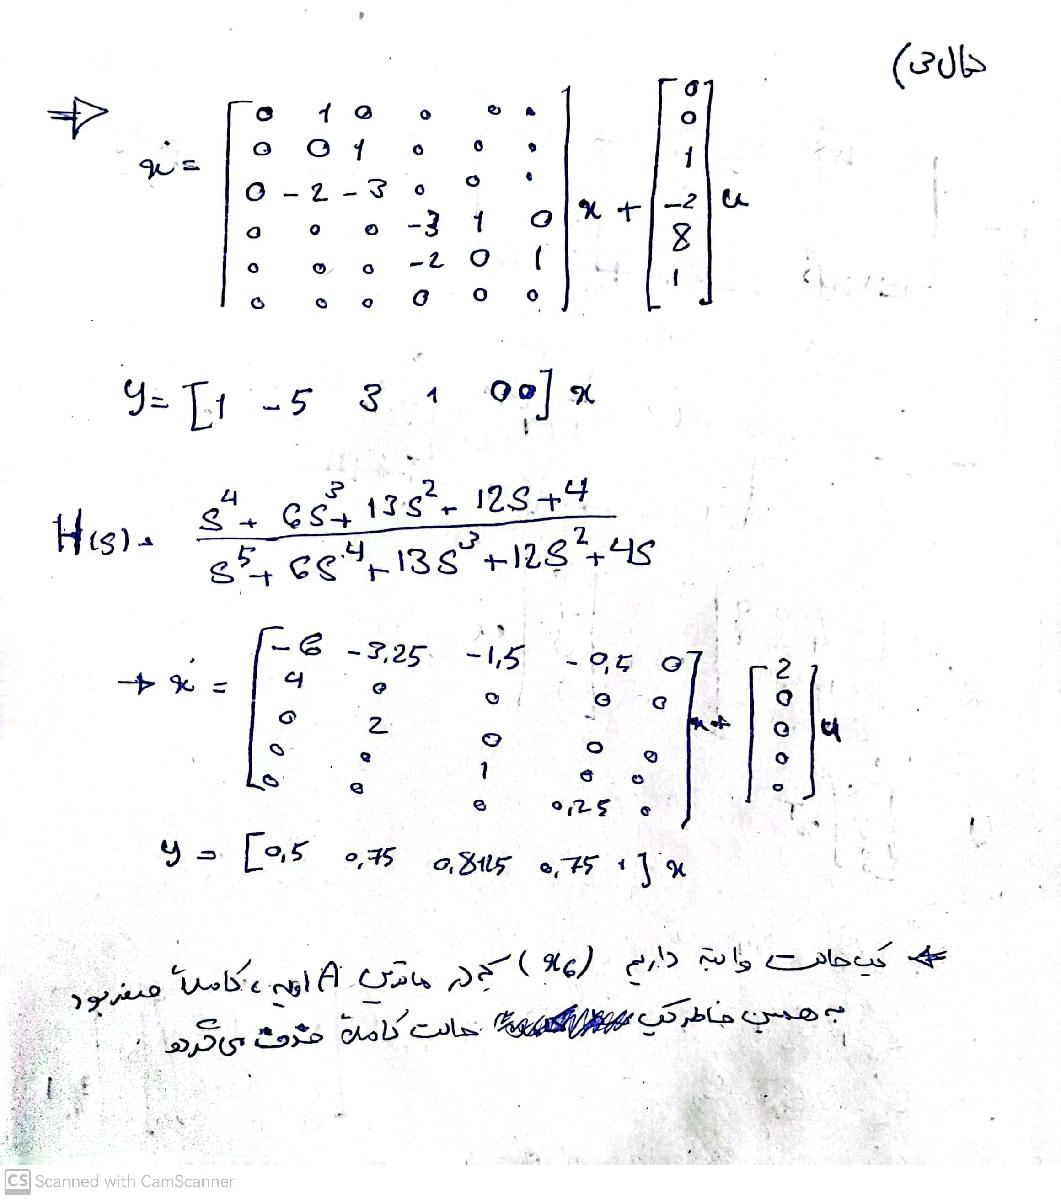


A1 = [0 1 0 ;0 0 1;0 -2 -3];
A2 = [-3 1 0;-2 0 1;0 0 0];
A = [A1 zeros([3 3]);zeros([3 3]) A2];

B = [0 0 1 -2 8 1]';
C = [1 -5 3 1 0 0];
D = [0];
sys = ss(A,B,C,D)

sys =
 
  A = 
       x1  x2  x3  x4  x5  x6
   x1   0   1   0   0   0   0
   x2   0   0   1   0   0   0
   x3   0  -2  -3   0   0   0
   x4   0   0   0  -3   1   0
   x5   0   0   0  -2   0   1
   x6   0   0   0   0   0   0
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
   x4  -2
   x5   8
   x6   1
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1  -5   3   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




sys_tf=tf(sys);


sys_tfs = tf([1 6 13 12 4],[1 6 13 12 4 0])

sys_tfs =
 
    s^4 + 6 s^3 + 13 s^2 + 12 s + 4
  -----------------------------------
  s^5 + 6 s^4 + 13 s^3 + 12 s^2 + 4 s
 
Continuous-time transfer function.



sys_s = ss(sys_tfs)

sys_s =
 
  A = 
          x1     x2     x3     x4     x5
   x1     -6  -3.25   -1.5   -0.5      0
   x2      4      0      0      0      0
   x3      0      2      0      0      0
   x4      0      0      1      0      0
   x5      0      0      0   0.25      0
 
  B = 
       u1
   x1   2
   x2   0
   x3   0
   x4   0
   x5   0
 
  C = 
           x1      x2      x3      x4      x5
   y1     0.5    0.75  0.8125    0.75       1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



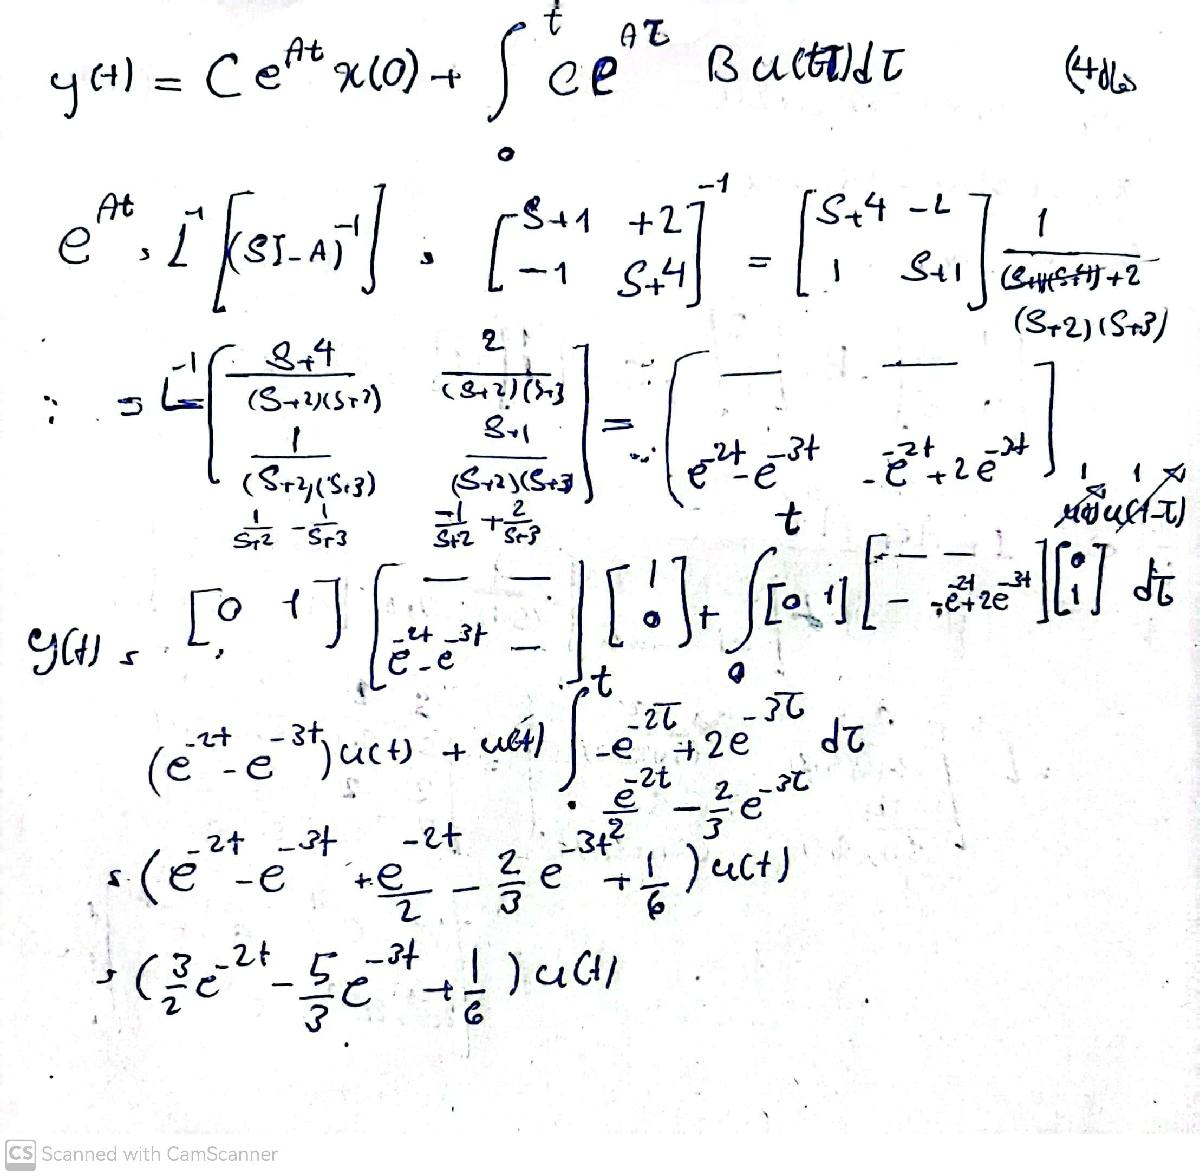

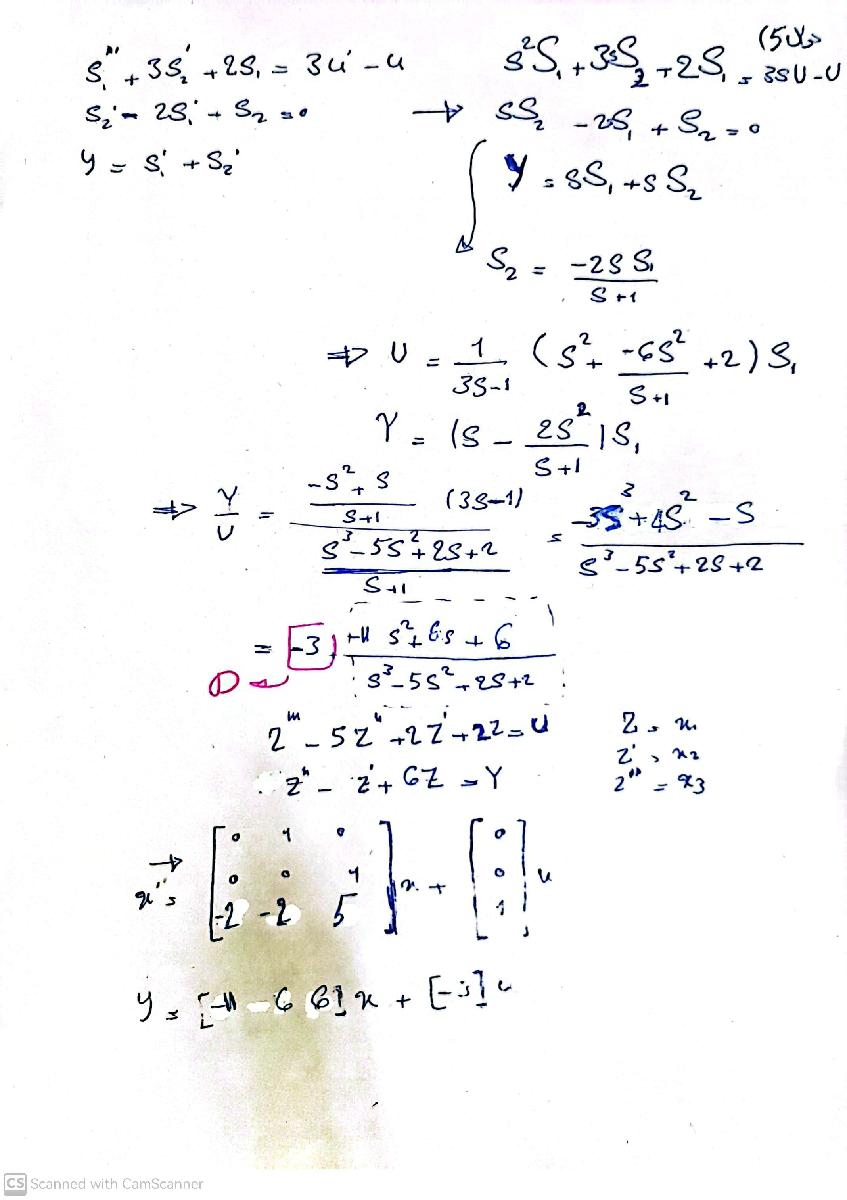

# MATLAB Assignments

clc
close all
clear all

# 6 Canonical Form Representation of Transfer Functions

% Define a transfer function
num = [11 12 13];
den = [1 2 3 4 5];
sys = tf(num, den)

sys =
 
       11 s^2 + 12 s + 13
  -----------------------------
  s^4 + 2 s^3 + 3 s^2 + 4 s + 5
 
Continuous-time transfer function.



[A, B, C] = canonicalForms(sys, "C")

A =      0     1     0     0
     0     0     1     0
     0     0     0     1
    -5    -4    -3    -2


B =      0
     0
     0
     1


C =     13    12    11     0


[A, B, C] = canonicalForms(sys, "O")

A =     -2     1     0     0
    -3     0     1     0
    -4     0     0     1
    -5     0     0     0


B =      0
    11
    12
    13


C =      1     0     0     0


# 7 Response of LTI State-Space Models using lsim

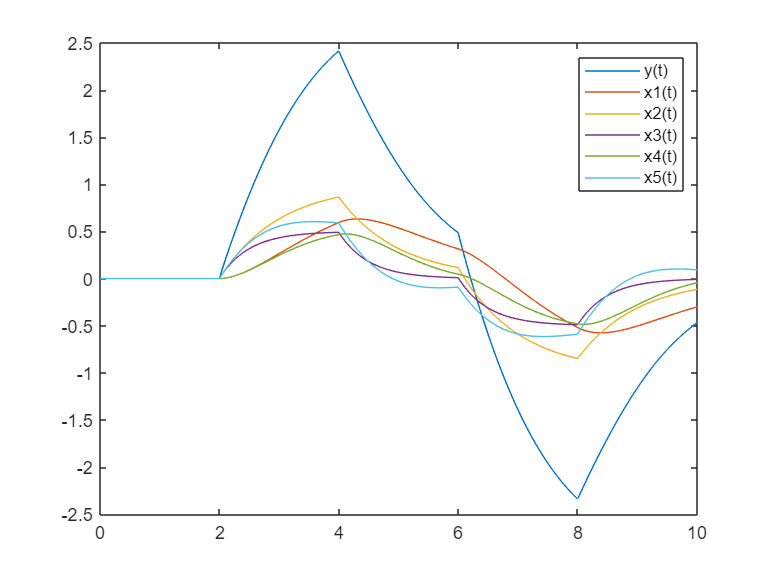

A = [-1 1 0 0 0; 0 -1 0 0 0; 0 0 -2 0 0; 0 0 0 -1 1; 0 0 0 -1 -1];
B = [0 1 1 0 1]';
C = [1 1 1 1 0];
D = [0];

sys = ss(A, B, C, D);
t = 0:0.01:10;
u =  Step01(t-2)-Step01(t-4)-Step01(t-6)+Step01(t-8);
x0 = [0, 0, 0, 0, 0];
[y, tOut, x] = lsim(sys, u, t, x0);

figure
plot(t,y,t,x)
legend("y(t)","x1(t)","x2(t)","x3(t)","x4(t)","x5(t)")

# 8 Response of LTI State-Space Models using Euler Method

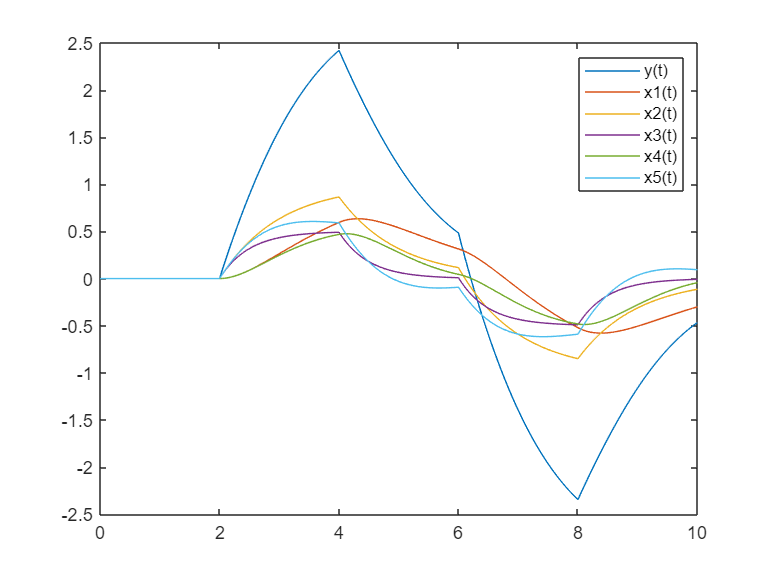

A = [-1 1 0 0 0; 0 -1 0 0 0; 0 0 -2 0 0; 0 0 0 -1 1; 0 0 0 -1 -1];
B = [0 1 1 0 1]';
C = [1 1 1 1 0];
D = [0];
Ts = 0.01;
t = 0:0.01:10;
u =  Step01(t-2)-Step01(t-4)-Step01(t-6)+Step01(t-8);
X = zeros([length(A), length(t)]);
x0 = [0;0;0;0;0];
X(:, 1) = x0;
Y = zeros(size(t));
Y(1) = C * x0;
for i=2:length(t)
X(:, i) = X(:, i-1) + Ts * (A * X(:, i-1) + B * u(i-1));
Y(i) = C * X(:, i) + D * u(i);
end

figure
plot(t,Y,t,X)
legend("y(t)","x1(t)","x2(t)","x3(t)","x4(t)","x5(t)")

# 9 Response of Nonlinear State-Space Models

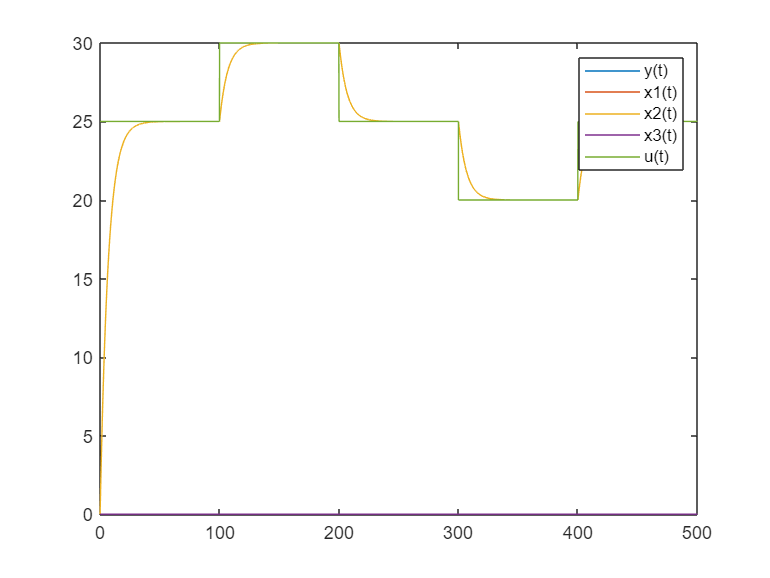

Ts = 0.01;
t = 0:0.01:500;
x0 = [0; 0; 0];
X = zeros([length(x0), length(t)]);
X(:, 1) = x0;
u = 25+5*(Step01(t-100)-Step01(t-200))-5*(Step01(t-300)-Step01(t-400));

for i=2:length(t)
X(:, i) = X(:, i-1) + Ts * f(X(:, i-1), u(i-1));
Y(i) = g(X(:, i));
end
figure
plot(t,Y,t,X,t,u)
legend("y(t)","x1(t)","x2(t)","x3(t)","u(t)")

# 10 State-Space Implementation using Simulink

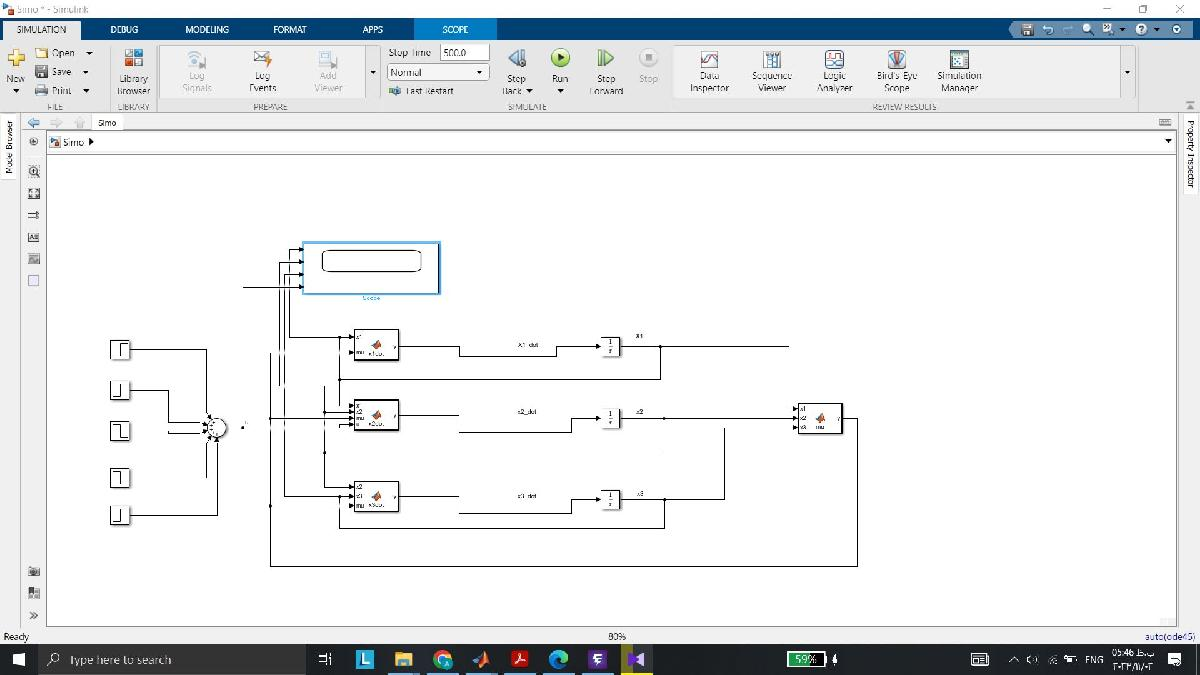

min step size(slow=0.1 suitable=1 fast=10)

ode 45 (slow suitable fast)

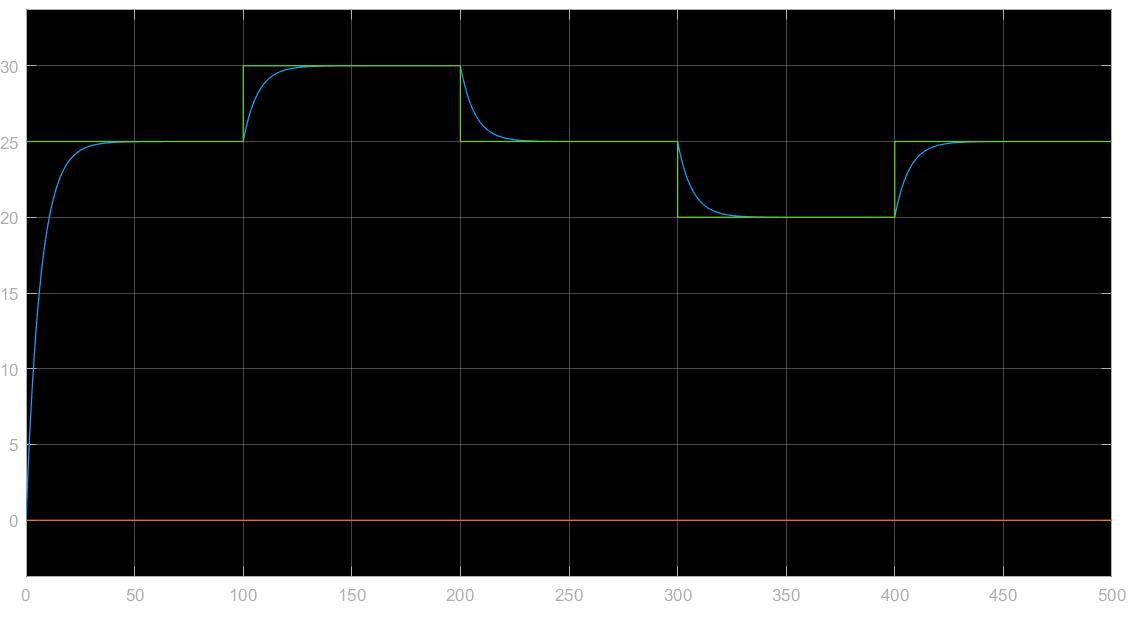

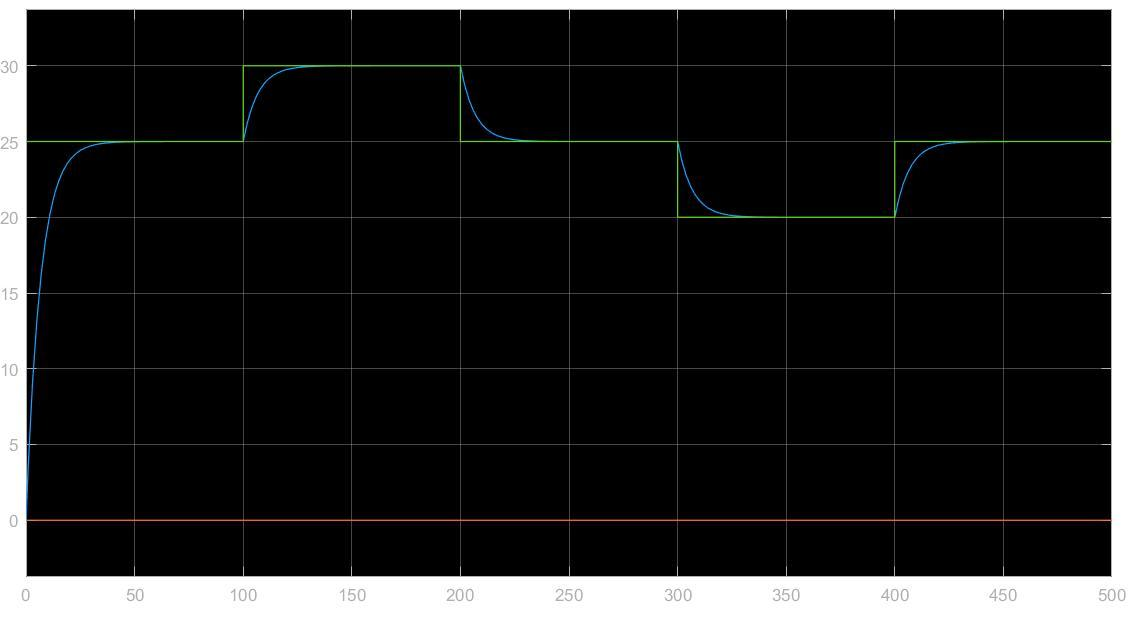

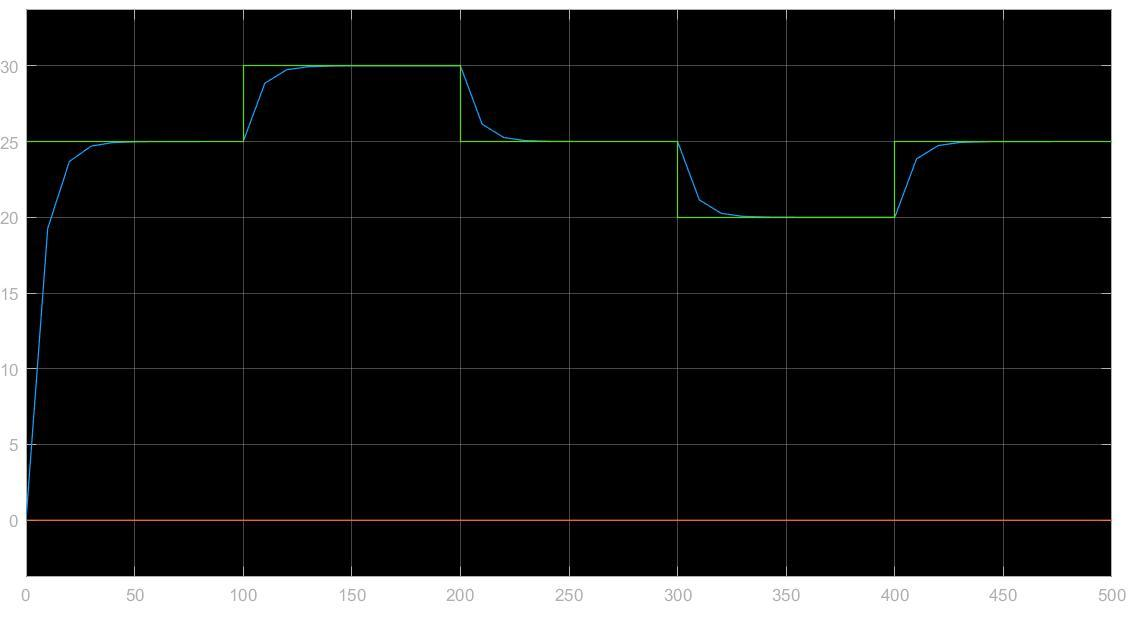

ode 15 (slow suitable fast)

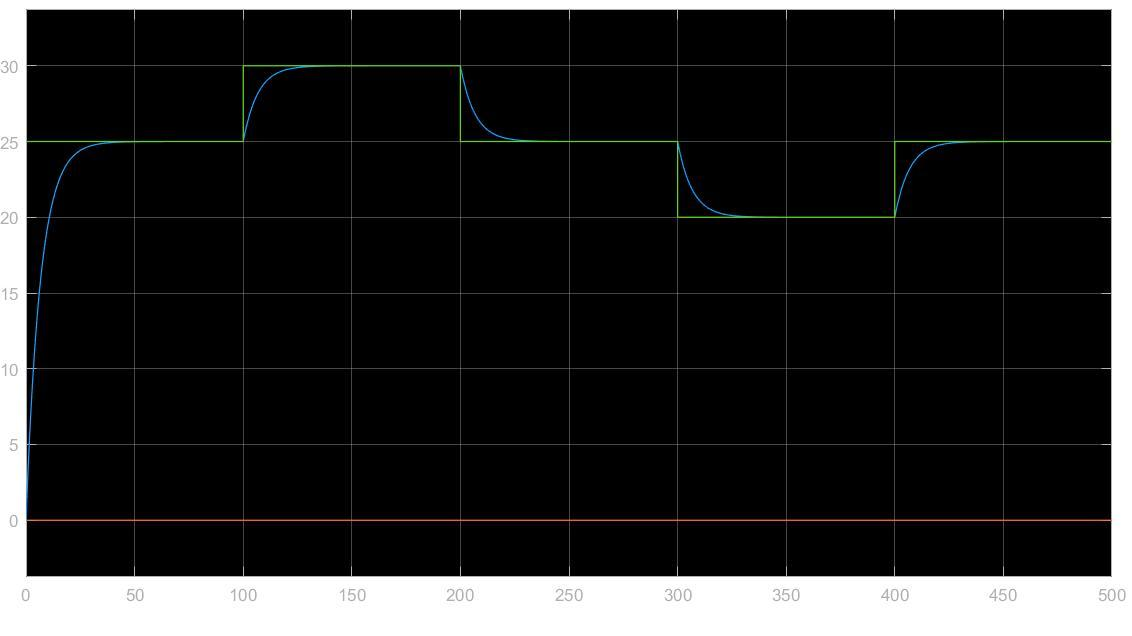

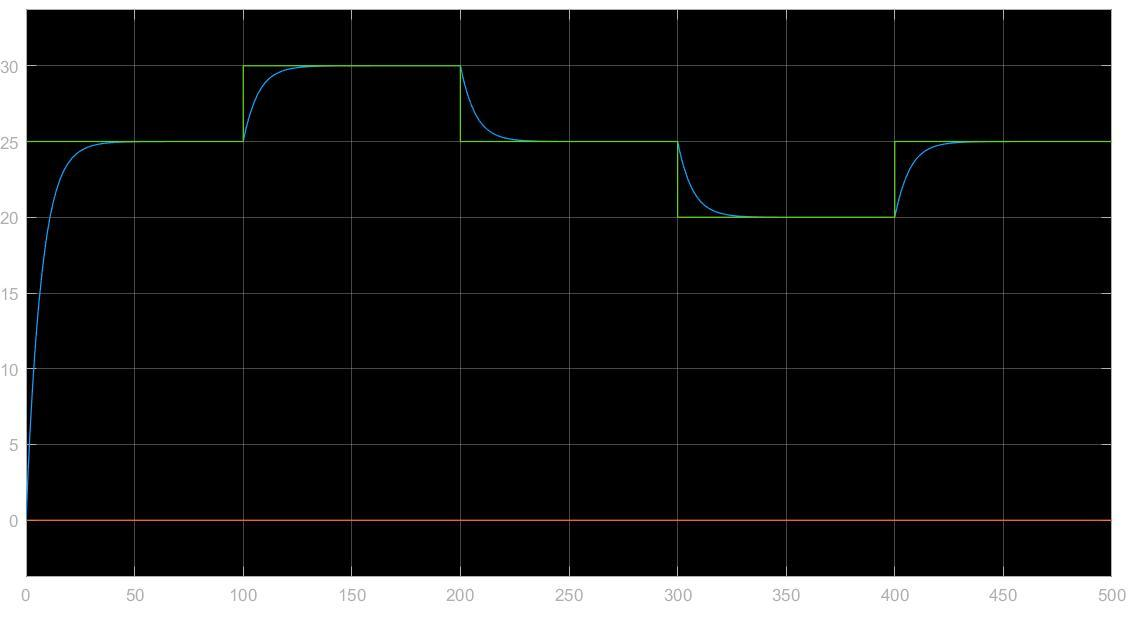

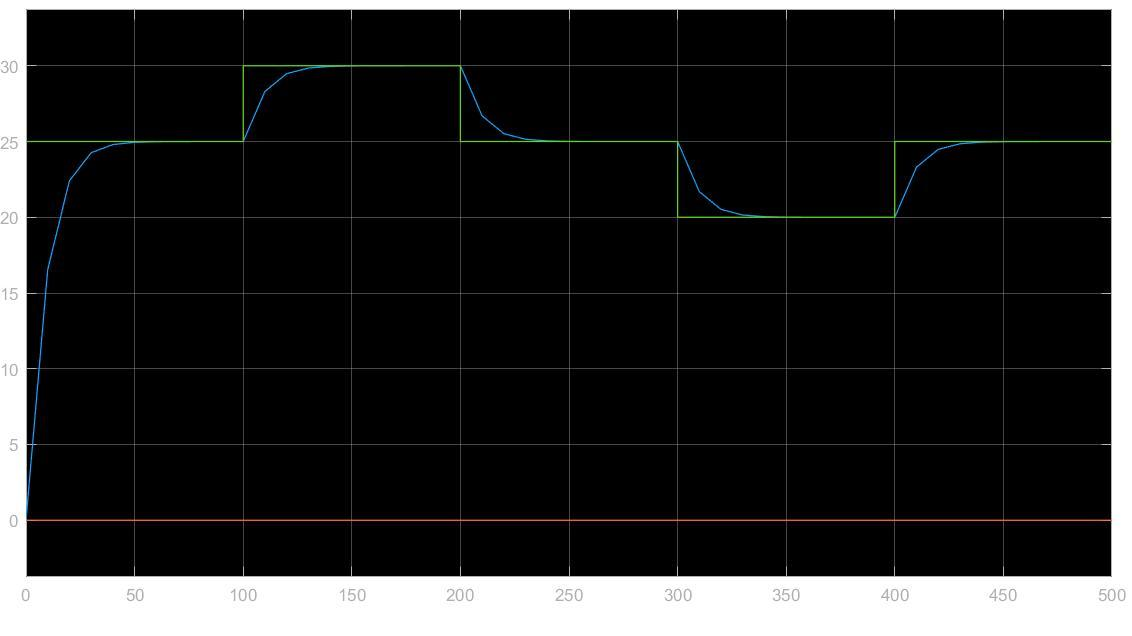

ode 23s (slow suitable fast)

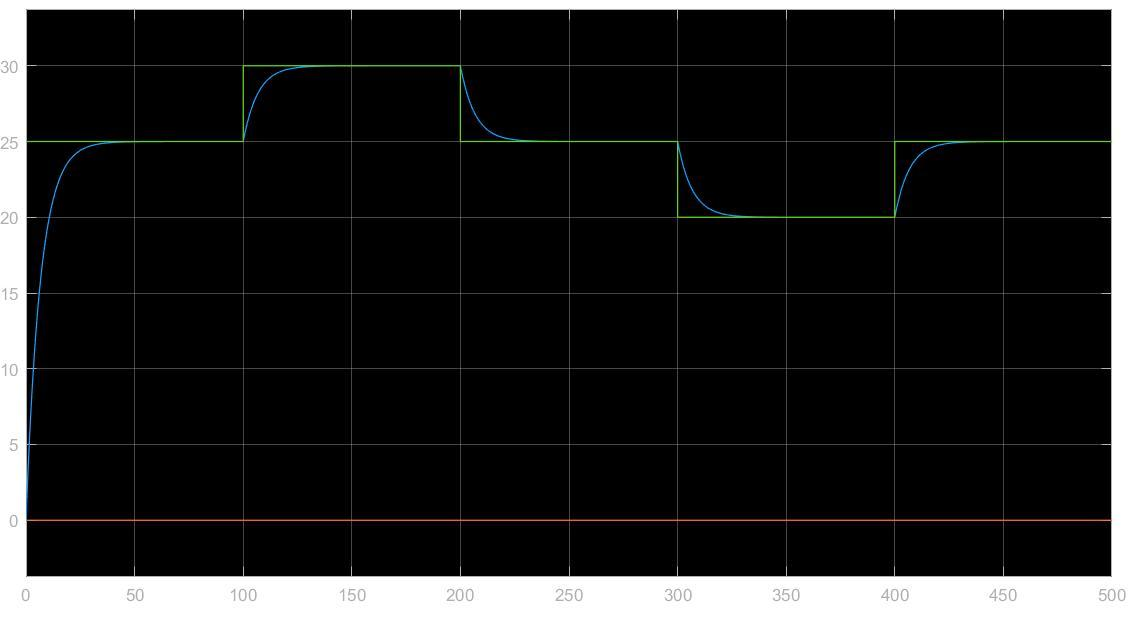

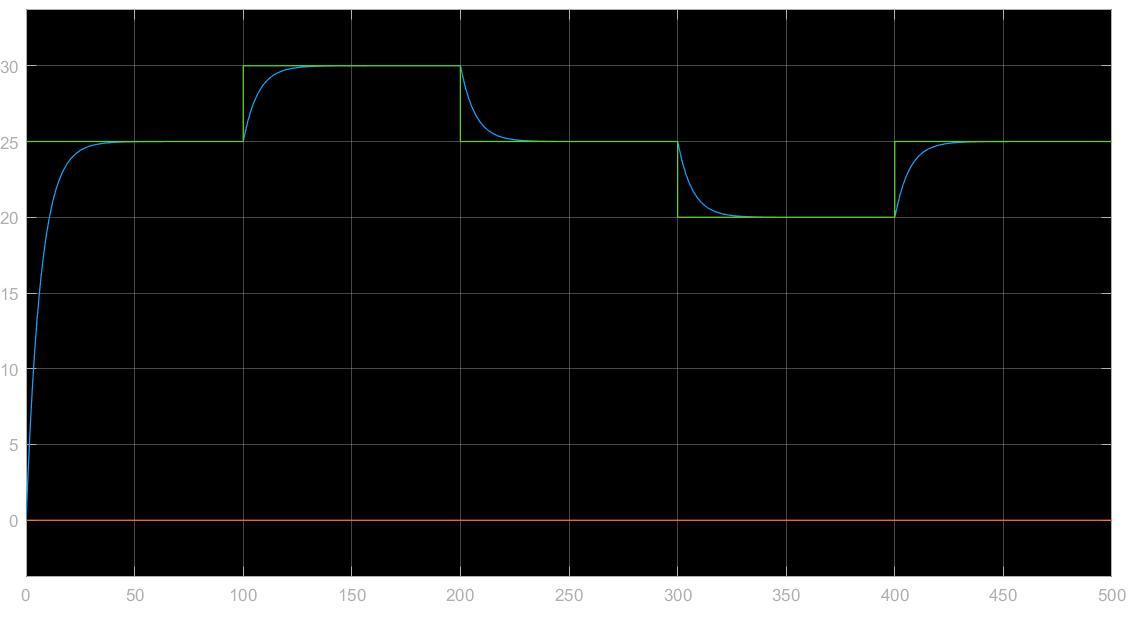

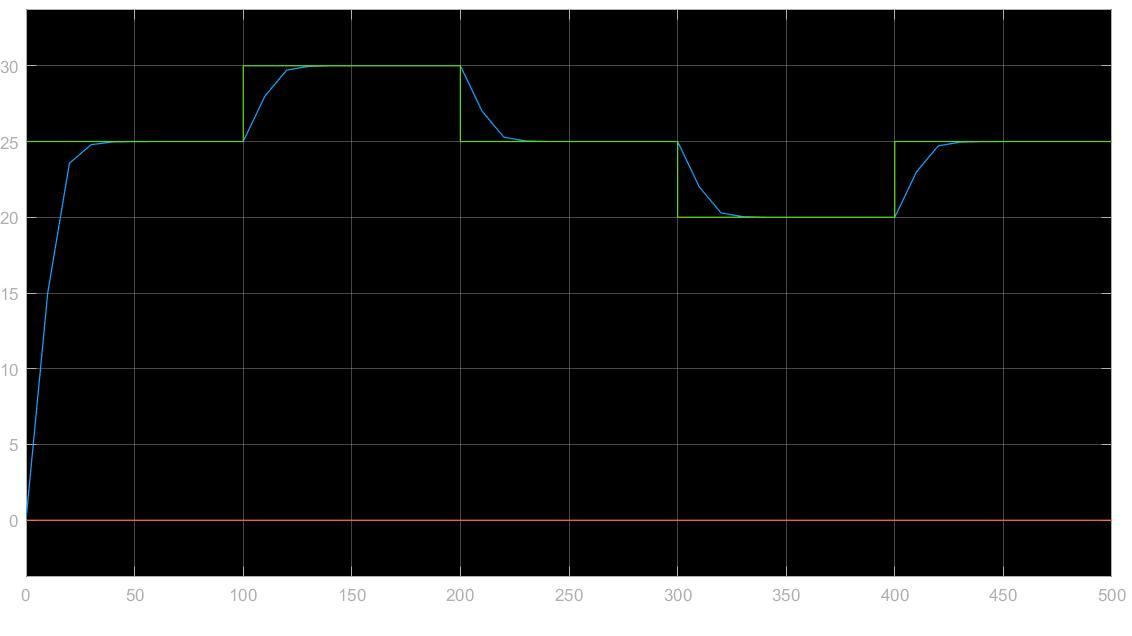

function [A, B, C] = canonicalForms(sys, form)

if ~isproper(sys)
    error("The input transfer function must be strictly proper.")
end

switch upper(form)
    case "C"
        [A, B, C] = controlabe(sys);
    case "O"
        [A, B, C] = observable(sys);
    otherwise
        error("Invalid canonical form. Please enter 'C' for controllable" + ...
            " canonical form or 'O' for observable canonical form.")
end
end
function [A,B,C] = controlabe(sys)
a = sys.Denominator{1,1};
n = size(a,2);
a = a(2:end);
b = sys.Numerator{1,1};
b = b(2:end);

n = n-1 ;
a = flip(a);
b = flip(b);
 
A = eye(n);
A = circshift(A,1,2);
A(n,1) = 0;
A(n,:) = -a;

B = zeros([n 1]);
B(n) = 1;

C = b;

end
function [A,B,C] = observable(sys)
a = sys.Denominator{1,1};
n = size(a,2);
a = a(2:end);
b = sys.Numerator{1,1};
b = b(2:end);

n = n-1;
A = eye(n);
A = circshift(A,1,2);
A(n,1) = 0;
A(:,1) = -1 * a';

B = zeros([n 1]);
B = b';

C = zeros([1 n]);
C(1) = 1;

end


function y = g(x, u)
y =  x(3);
end
function dxdt = f(x, u)

mu = ( 0.48*(1-0.02*x(3))*x(2) )/( 1.2+x(2)+( (x(2)^2)/22 ) );

dxdt = [-0.15*x(1)+mu*x(1);
        0.15*(u - x(2))-2.5*mu*x(1);
        -0.15*x(3)+(2.2*mu+0.2)*x(1)];
end


function [u] = Step01(C)
u = C;
s = length(C);
for i=1:s
    if C(i)>=0
        u(i)=1;
    else
        u(i)=0;
    end
end    
end
function [u] = Step00(C)
u = C;
s = length(C);
for i=1:s
    if C(i)>0
        u(i)=1;
    else
        u(i)=0;
    end
end    
end

